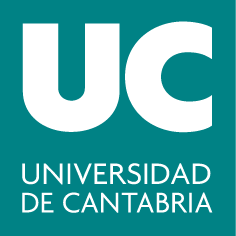

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 4: Integrales triples y teorema del valor medio**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Calcular integrales triples de forma exacta, con cálculo simbólico, en coordenadas cilíndricas y esféricas.

- Aplicación del Teorema del Valor Medio para funciones de tres variables.

- Dibujar superficies utilizando ecuaciones paramétricas (coordenadas cilíndricas y esféricas).

### Resumen teórico

#### Integral triple

Sea $f$ una función tres dos variables definida sobre una caja $H$ . Si para toda partición de $H$, tal que la norma de la partición tiende a cero ($\mid\mid R \mid \mid \rightarrow 0$, entonces el número de particiones tiende a infinito), existe el límite:


$$\displaystyle \lim_{p\to\infty} \Big( \sum_{k=1}^{p} f(x_{k}, y_{k}, z_{k})\Delta V_{k}\Big)$$


 se dice que $f$** es integrable en **$H$.

Además, el valor de este límite es la integral triple de $f$ sobre $H$ y se denota por:


$$\displaystyle \int\int\int_{H}f(x,y,z) dV=\lim_{p\to\infty} \Big( \sum_{k=1}^{p} f(x_{k}, y_{k}, z_{k})\Delta V_{k}\Big)$$


#### Coordenadas Cilíndricas

Las coordenadas cilíndricas se obtienen utilizando coordenadas polares en uno de los planos coordenados y manteniendo la tercera variable. Suponiendo que la coordenada $z$ se mantenga, las ecuaciones del cambio de cartesianas a cilíndricas serán:


$$x=rcos\theta$$
    
$$y=rsen\theta$$
    
$$z=z$$


El Jacobiano en cilíndricas es     $J=\frac{\partial (x,y,z)}{\partial(r,\theta, z)}=r$     y el elemento diferencial de volumen $dV=rdrd\theta dz$

#### Coordenadas esféricas

Las ecuaciones del cambio de cartesianas a esféricas son:


$$x=\rho sen\phi cos\theta$$
    
$$y=\rho sen\phi sen\theta$$
    
$$z=\rho cos\phi$$


El Jacobiano en esféricas es     $J=\frac{\partial (x,y,z)}{\partial(\rho, \theta, \phi)}=\rho^{2}sen\phi$    y elelemento diferencial de volumen $dV=\rho^{2}\mid sen\phi \mid d\rho d\theta d\phi$

### Comandos útiles

#### Comandos para calcular de forma exacta la integral triple de una función sobre un dominio cerrado y acotado

- `syms x y z`: Declara las variables simbólicas `x y z.`

- `int(int(int(f(x,y,z), z, psi1(x,y), psi2(x,y)), y, phi1(x), phi2(x)), x, a, b)`: para calcular la integral triple:


$$\int_{a}^{b}\int_{\phi_{1}(x)}^{\phi_{2}(x)}\int_{\psi_{1}(x,y)}^{\psi_{2}(x,y)} f(x,y,z) dz dy dx$$


- `double(x): `Convierte a decimal con doble precisión los valores recogidos en x, que puede ser una matriz o vector de valores. 

**Comandos para repesentar superficies:**

- `surf(X,Y,Z,C)`: representar superficie `Z` sobre la malla creada por `X,Y` con el color según `C`. Importante: `X, Y, Z` son coordenadas cartesianas.

[X, Y]=meshgrid(0:0.05:2, 0:0.05:2);
surf(X, Y, X.^2 + Y, Y) % colorea según el valor de y

- `shading interp`: interpolar los colores de la figura.

- `colorbar`: incluye una leyenda de color en la figura.

- `xlabel('X'); ylabel('Y'); zlabel('Z')`: pone etiquetas a los ejes.

surf(X, Y, X.^2 + Y, Y)
shading interp
colorbar
xlabel('X'); ylabel('Y'); zlabel('Z')

- `set(h1, Atributo, Valor)`: establecer propiedades de la figura h, tales como transparencia, color de la rejilla, etc.

h= surf(X, Y, X.^2 + Y);
set(h,'FaceColor','magenta', 'FaceAlpha',0.4, 'EdgeColor','w')

### Ejercicios resueltos

**1.Representación de superficies en paramétricas. Coordenadas cilíndricas y esféricas.**

a) Tomando como parámetros las coordenadas cilíndricas $\theta \in [0, 2\pi], z\in [0,3]$ dibuja en la figura 1 el cilindro de ecuación $x² +y^2=9$. 

b) Utilizando como parámetros las coordenadas esféricas $\theta\in[0,2\pi], \phi\in [0, \pi]$ dibuja en la figura 2 la esfera $x^2+y^2+z² =2$.

a) Tomando como parámetros las coordenadas cilíndricas $\theta \in [0, 2\pi], z\in [0,3]$ dibuja en la figura 1 el cilindro de ecuación $x² +y^2=9$. 

Tenemos que expresar el **cilindro** en cilíndricas: $x^2+y^2=9 \Rightarrow r^2=9 \Rightarrow r=3$

Así que las ecuaciones paramétricas para dibujar la superficie serían: $x=3cos\theta, y=3sen\theta, z=z$

figure(1)
% Definir los vectores de las coordenadas cilíndricas t, z para construir
% la malla
t=linspace(0,2*pi,40);
z=linspace(0,3,20);
[T,Z]=meshgrid(t,z);
% pasar de cilíndricas a cartesianas
X=3*cos(T); Y=3*sin(T); Z=Z;
% representar
surf(X,Y,Z)
axis equal
xlabel('X'); ylabel('Y'); zlabel('Z')
title('cilindro circular x^2+y^2=9')
shading interp

b) Utilizando como parámetros las coordenadas esféricas $\theta\in[0,2\pi], \phi\in [0, \pi]$ dibuja en la figura 2 la esfera $x^2+y^2+z² =2$.

Tenemos que expresar la **esfera** en esféricas: $x^2+y^2+z² =2\Rightarrow \rho^2=2 \Rightarrow \rho=\sqrt{2}$

Así que las ecuaciones paramétricas para dibujar la superficie serían: $x=\sqrt{2}sen\phi cos\theta, y=\sqrt{2}sen\phi sen\theta, z=\sqrt{2}cos\phi$

figure(2)
% Definir los vectores de las coordenadas esféricas t, fi para construir la
% malla
t=0:pi/30:2*pi;
fi=0:pi/30:pi;
[T,FI]=meshgrid(t,fi);
% pasar de esféricas a cartesianas
X=sqrt(2)*sin(FI).*cos(T);   
Y= sqrt(2)*sin(FI).*sin(T); 
Z=sqrt(2)*cos(FI);  
% representar
surf(X,Y,Z)
axis equal
xlabel('X'); ylabel('Y'); zlabel('Z')
title('esfera x^2+y^2+z^2=2')
shading interp

**2. Coordenadas cilíndricas y esféricas. Cálculo de la temperatura media de un sólido.**

Se considera el sólido $H$ que ocupa la región limitada por dos paraboloides, inferiormente por $z_{2}=x^2+y^2$ y superiormente por $z_{1}=2-x^2-y^2$. 

a) Dibujar en un mismo gráfico los dos paraboloides usando coordenadas cilíndricas, considerando $r \in [0, 1]$, $\theta \in [0, 2\pi]$.

b) Calcular el volumen del sólido $H$, planteando la integral correspondiente en coordenadas cilíndricas.

c) Sabiendo que cada punto de $H$ está a una temperatura dada por $T(x,y,z)=x^2+y^2+(z-1)^2$, calcular la temperatura media de $H$.

d) Dibujar el lugar geométrico donde se alcanza la temperatura media.

a) Dibujar en un mismo gráfico los dos paraboloides usando coordenadas cilíndricas, considerando $r \in [0, 1]$, $\theta \in [0, 2\pi]$.

En primer lugar, expresamos los dos **paraboloides** que limitan $H$ en coordenadas cilíndricas:


$$z_{1}=r^{2}cos^{2}\theta + r^{2}sen^{2}\theta =r^2$$



$$z_{2}= 2- r^{2}cos^{2}\theta -r^{2}sen^{2}\theta=2-r^2$$


Esos paraboloides se cortan en $r^{2}=2- r^{2} \Rightarrow 2r^{2}=2 \Rightarrow r=1$, es decir, en la circunferencia de radio 1 centrada en $(0,0,1)$, pues $z_1=z_2=1$ para ese radio.

Por lo tanto, se define el dominio en cilíndricas: $H= \lbrace (r,\theta, z) /0\leq \theta \leq 2\pi, 0\leq r \leq 1, r^{2} \leq z \leq 2-r^{2} \rbrace$

%Define el vector de valores del parámetro r de cilíndricas
r=linspace(0,1,20);
%Define el vector de valores del ángulo theta de cilíndricas
t=linspace(0,2*pi,40); 
%Genera la malla con las coordenadas cilíndricas (R,T) de los nudos
[R,T]=meshgrid(r,t); 
%Ecuaciones paramétricas de los paraboloides z1=2-x^2-y^2, z2=x^2+y^2
X=R.*cos(T); Y=R.*sin(T);  Z1=2-R.^2; Z2=R.^2; 
%Dibuja el paraboloide superior con transparencia 0.4 y retícula blanca
h1=surf(X,Y,Z1);
set(h1,'FaceAlpha',0.4, 'EdgeColor','w')
shading interp
hold on
%Dibuja el paraboloide inferior con transparencia 0.4 y retícula blanca
h2=surf(X,Y,Z2);
set(h2,'FaceAlpha',0.4, 'EdgeColor','w')
shading interp
axis equal
colorbar
xlabel('X'); ylabel('Y'); zlabel('Z')

b) Calcular el volumen del sólido $H$, planteando la integral correspondiente en coordenadas cilíndricas.

Considerando el dominio $H= \lbrace (r,\theta, z) /0\leq \theta \leq 2\pi, 0\leq r \leq 1, r^{2} \leq z \leq 2-r^{2} \rbrace$ y el Jacobiano en cilíndricas, la integral que hay que calcular es:


$$\text{Volumen}=\int_{0}^{2\pi}\int_{0}^{1}\int_{r^{2}}^{2-r^{2}} r dz dr d\theta$$


syms r t z
volumen=int(int(int(r,z,r^2,2-r^2),r,0,1),t,0,2*pi)

c) Sabiendo que cada punto de $H$ está a una temperatura dada por $T(x,y,z)=x^2+y^2+(z-1)^2$, calcular la temperatura media de $H$.

Usando el cambio a cilíndricas, la temperatura será: $T(r,\theta, z)=r^{2}cos^{2}\theta +r^{2}sen^{2}\theta + (z-1)^{2}=r^{2}+(z-1)^{2}$

Por lo tanto, la temperatura media será: $\text{Temperatura Media}=\displaystyle\frac{\int_{0}^{2\pi}\int_{0}^{1}\int_{r^{2}}^{2-r^{2}} \Big(r^{2}+ (z-1)^{2} \Big)r dz dr d\theta}{\text{Volumen}}$

Tmedia=int(int(int((r^2+(z-1)^2)*r,z,r^2,2-r^2),r,0,1),t,0,2*pi)/volumen

d) Dibujar el lugar geométrico donde se alcanza la temperatura media.

El lugar geométrico donde se alcanza esa temperatura media es: $T(x,y,z)=\frac{1}{2} \Rightarrow x^{2}+y^{2}+(z-1)^{2}=\frac{1}{2}$

que es la **esfera** de centro $(0,0,1)$ y radio $\frac{1}{\sqrt{2}}$ (resulta más conveniente representarla definiéndola en coordenadas esféricas).

%Define el vector de valores del ángulo theta de esféricas
t=0:pi/30:2*pi;
%Define el vector de valores del ángulo fi de esféricas
fi=0:pi/30:pi; 
%Genera la malla con las coordenadas esféricas (T,FI) de los nudos
[T,FI]=meshgrid(t,fi); 
%Escribe las ecuaciones paramétricas de la esfera de centro (0,0,1) y radio R=1/sqrt(2)
X= sqrt(1/2)*sin(FI).*cos(T);   
Y= sqrt(1/2)*sin(FI).*sin(T); 
Z=1+ sqrt(1/2)*cos(FI);  % centro desplazado: z=z0+ rho*cos(fi)
%Dibuja la esfera en color negro, con transparencia 0.4
h3=surf(X,Y,Z);
set(h3,'FaceAlpha',0.4,'FaceColor','k')
title('Paraboloides y esfera en su interior')
hold off